# [IPSA] - Automatique - Projet drone

# Document principal - Partie 02

Auteur : Adrien Jacob 

La partie 01 était très guidée pour comprendre les concepts principaux. Pour la suite de l'étude, partons d'un script neuf, plus direct.

**====> Il est inutile de commencer cette partie avant d'avoir terminé entièrement la partie 01 <====**

**Objectif de cette partie : **

- Construire une commande en vitesse, indépendante de la distance à parcourir

- Améliorer le modèle avec les saturations actionneurs et l'ajout de perturbations

- Concevoir un design de contrôle LQR optimisé pour la course (partie 03) et comparer les résultats pour argumenter le choix de design

clc; clear; close all;
addpath Images\ Simulink\ Parametres_modelisations\
dt_realtime = 1/40; % cf partie 01

## **Initialisation **

**Import du modèle et paramètres du drone :**

evalc drone_parameters_corrige; % donne la structure params
evalc drone_modelisation_corrige; % donne le modèle linéarisée sysBO et A,B_mot,C,D

A = sysBO.A;
B = sysBO.B; % = B_mot (cf. script)
C = sysBO.C;
D = sysBO.D;

**Asservissement consigne :**

Cs = C([1 3 5 11],:);

**Paramètres de simulation ***(pour l'ensemble des simulations de ce script)*

***P.S. ****même chose que partie 01*

% StopTime = ...
% x_init = ...
% y_ref = ... % format timeseries

% Unreal Engine :
bool.Unreal_Engine = true; % active/desactive le bloc Unreal Engine

% Paramètres pour la fonction d'annimation
clear options; options.speed_ratio = 2;
% options.record_video = true; % options.video_filename = 'no_name';

______________________________________________________________________________________________

**Design 01 (partie 01) : placement de pôles manuel*** (à compléter)*

***P.S. ****même chose que partie 01*

______________________________________________________________________________________________

p_x =       [-0.5+0.3i, -0.5-0.3i];
p_y =       [-0.5+0.3i, -0.5-0.3i];
p_z =       [-0.5, -0.6];
p_phi =     [-3, -3.2];
p_theta =   [-3, -3.2];
p_psi =     [-2, -2.2];

p_default = [p_x p_y p_z p_phi p_theta p_psi];

sysBO_default = sysBO; 
% K_default = ...
% N_default = ...
% sysBF_default = ...

**______________________________________________________________________________________**

## 1. Ajout des limitations actionneurs

Le document de paramètres a définit les vitesses au carrée maximales atteignable par les moteurs : `params.Wmot2_sat `

A partir de ces données, ajoutez les saturations des moteur au niveau de l'entrée du système $u_M$

**P.S. **

- **Attention, **la linéarisation du modèle s'est faite autour du vol stationnaire, les limites correspondent donc aux marges au dessus / dessous de `params.Wmot2_hover`

- **Attention, **le ***u** du bloc gain est un artefact visuel indiquant l'option de multiplication matritielle K*u dans les options du bloc.

        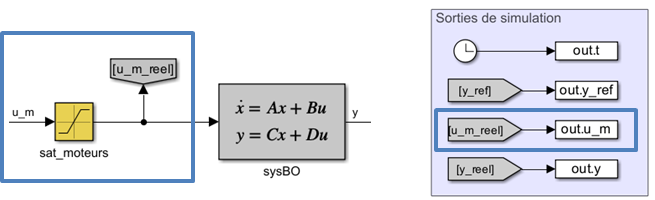      

**______________________________________________________________________________________**

## **2. Ajout d'un pré-filtrage de consigne**

L'asservissement en consigne de position du drone crée un problème de dimensionnement à mesure que l'on augmente la distance à parcourir.

- Dépassements du domaine d'approximation linéaire pour le pitch / roll (modèle linéaire non valide).

- Saturations excessives des moteurs (non-linéarités et perte de control).

L'idée est alors d'asservir la position du drone avec une consigne en rampe au lieu d'une consigne en échelon

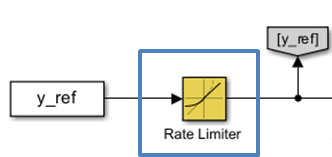        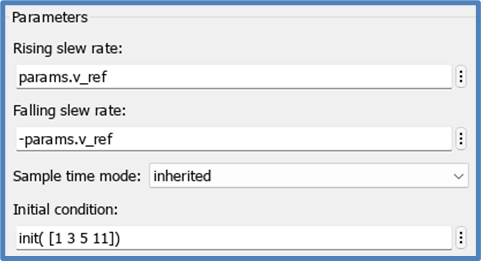

**______________________________________________________________________________________**

## **3. Ajout de perturbations**

**==> complétez le script **`perturbations_parameters.mlx`

evalc perturbations_parameters; % import de la structure pert. (à compléter)

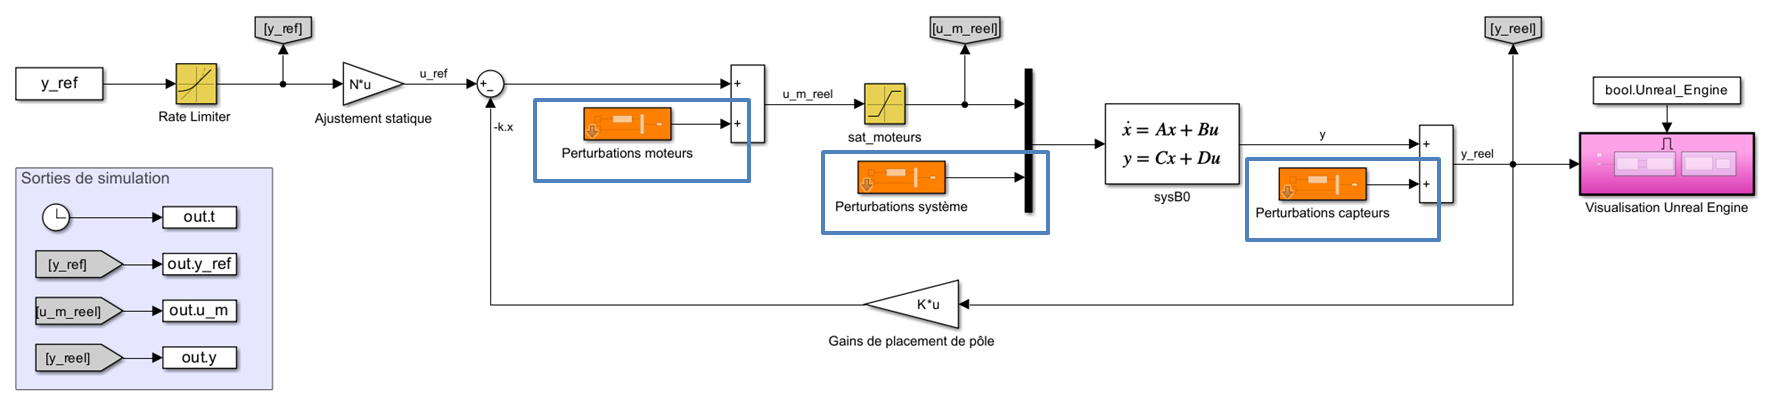

On modélisera le vent comment un jeu de forces / couples perturbateurs sur l'ensemble des axes, subissant l'inertie associée.

**On regroupe donc 6 perturbations distinctes :**

ainsi : $B_{\textrm{vent}} \ldotp d_{\textrm{vent}} =\left(\begin{array}{cccccc}
0 & 0 & 0 & 0 & 0 & 0\\
\frac{1}{m} & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & \frac{1}{m} & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & \frac{1}{m} & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & \frac{1}{I_x } & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & \frac{1}{I_y } & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & \frac{1}{I_z }
\end{array}\right)\ldotp \left\lbrack \begin{array}{c}
F_{x,\textrm{vent}} \\
F_{y,\textrm{vent}} \\
F_{z,\textrm{vent}} \\
C_{x,\textrm{vent}} \\
C_{y,\textrm{vent}} \\
C_{z,\textrm{vent}} 
\end{array}\right\rbrack$   ;   $D_{\textrm{vent}} \ldotp d_{\textrm{vent}} =\left(\begin{array}{cccccc}
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right)\ldotp \left\lbrack \begin{array}{c}
F_{x,\textrm{vent}} \\
F_{y,\textrm{vent}} \\
F_{z,\textrm{vent}} \\
C_{x,\textrm{vent}} \\
C_{y,\textrm{vent}} \\
C_{z,\textrm{vent}} 
\end{array}\right\rbrack \;$

L'intégration de la perturbation système se construit par **augmentation de l'entrée** : 

- 
$$\dot{x} =A\ldotp x+\left\lbrack \begin{array}{cc}
{\mathit{\mathbf{B}}}_{\textrm{mot}}  & {\mathit{\mathbf{B}}}_{\textrm{vent}} 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
{\mathit{\mathbf{u}}}_{\mathit{\mathbf{M}}} \\
{\mathit{\mathbf{d}}}_{\textrm{vent}} 
\end{array}\right\rbrack$$


- 
$$y=C\ldotp x+\left\lbrack \begin{array}{cc}
\mathit{\mathbf{D}} & {\mathit{\mathbf{D}}}_{\textrm{vent}} 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
{\mathit{\mathbf{u}}}_{\mathit{\mathbf{M}}} \\
{\mathit{\mathbf{d}}}_{\textrm{vent}} 
\end{array}\right\rbrack$$


Construisez les matrices  ${\mathit{\mathbf{B}}}_{\textrm{vent}}$ et ${\mathit{\mathbf{D}}}_{\textrm{vent}}$ :

% Bvent = ...
% Dvent = ...

**______________________________________________________________________________________**

## **4. Ajout d'un retour d'état intégral de consignes**

Afin de prendre en compte les écarts de modèle et les perturbations, nous allons augmenter le système avec les états intégral des erreurs de consignes :

La forme finale du modèle comporte donc :

- 16 états (dont 4 états intégrals)

- 10 entrées (dont 6 de perturbations)

        $\bar{\dot{x} } =\left\lbrack \begin{array}{c}
\dot{x} \\
\varepsilon_x \\
\varepsilon_y \\
\varepsilon_z \\
\varepsilon_{\psi } 
\end{array}\right\rbrack =A_{\textrm{aug}} \ldotp \left\lbrack \begin{array}{c}
x\\
\int \varepsilon_x \\
\int \varepsilon_y \\
\int \varepsilon_z \\
\int \varepsilon_{\psi } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
B_{\textrm{mot}\_\textrm{aug}}  & B_{\textrm{vent}\_\textrm{aug}} 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
u_M \\
d_{\textrm{vent}} 
\end{array}\right\rbrack$    ;     $y=x=C_{\textrm{aug}} \ldotp \left\lbrack \begin{array}{c}
x\\
\int \varepsilon_x \\
\int \varepsilon_y \\
\int \varepsilon_z \\
\int \varepsilon_{\psi } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
D_{\textrm{aug}}  & D_{\textrm{vent}\_\textrm{aug}} 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
u_M \\
d_{\textrm{vent}} 
\end{array}\right\rbrack$

        
$${\bar{x} }_{\textrm{init}} =\left\lbrack \begin{array}{c}
x_{\textrm{init}} \\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$


        **Attention**** : **Les conditions initiales peuvent être éloignées du point de linéarisation en $\left(x\;;y\;;z\;;\psi \right)=0$

        Dans ce cas il est nécessaire de précharger l'erreur de consigne intégrale pour éviter un saut de commande à t = 0.

**        Ainsi, on initialise l'état intégrale avec : **${x_i }_{\textrm{init}} =-\textrm{pinv}\left(\textrm{Ki}\right)*K*x_{\textrm{init}}$

        => A t = 0`, `$u\left(0\right)=-K\ldotp x\left(0\right)-K_i \ldotp \left(-K_i^{-1} \ldotp K\ldotp x\left(0\right)\right)=0$

        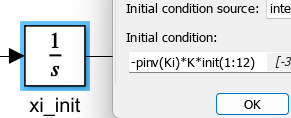

   **Nom du Simulink demandé :**  =====>  Simulink_drone_BF**_final  **<======    

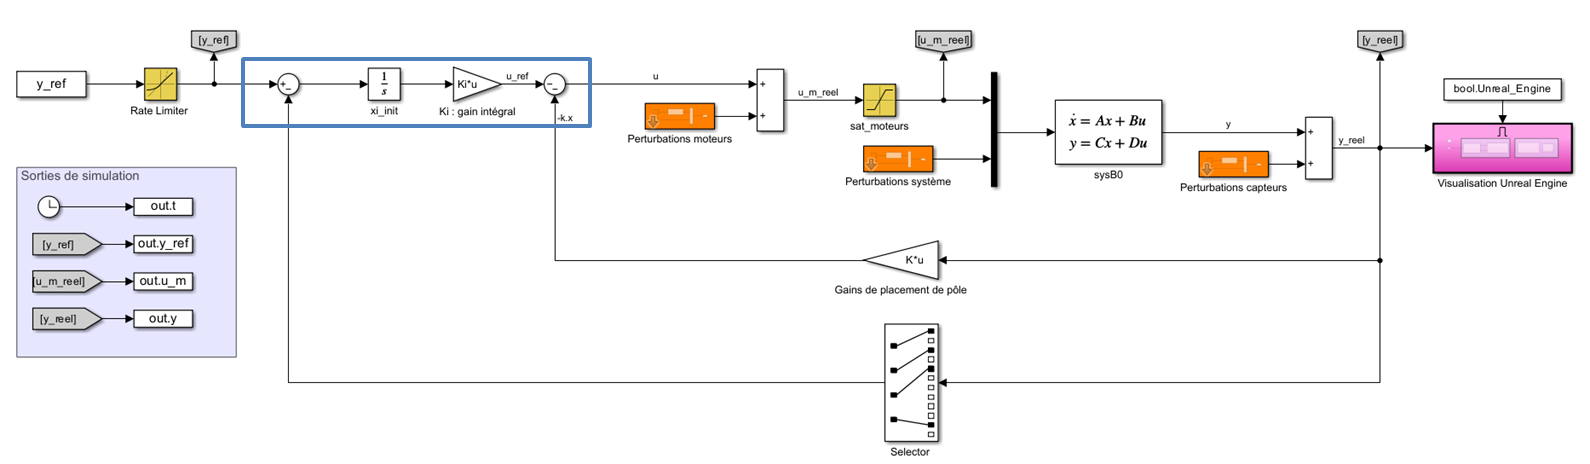

**Augmentation du système**

---------------------------------------------------------------------------------

**1/ Ajout des états intégrals**

[A_aug , B_aug , C_aug , D_aug] = augment_retour_int (A, B, C, D, Cs); % fonction en annexe donné (cf. cours 08)

**2/ Adaptation des perturbations **(aux bonnes dimensions)

% n_aug_int = ...
% n_aug_vent = ...
Bvent_aug = [Bvent ; zeros(n_aug_int,n_aug_vent)];
Dvent_aug = Dvent;

**3/ Adaptation du système augmenté  : sysBO_aug**

% x_init_aug = ...
% sysBO_aug = ...

## 5. Optimisation du contrôle

**/!\ Attention :**

- Cette partie est de loin la plus longue et la plus théorique, c'est aussi la plus grande valeure ajoutée de l'automaticien : régler les gains de contrôle en fonction des contraintes et objectifs visés

- Elle nécessitera de procéder par itération. Les résultats du design choisi devront être argumenté théoriquement en s'appuyant sur les résultats de simulations (graphique , fonction d'affichage).

**Le placement de pôles donné en partie 01 avait été réglé pour une consigne en échelon d'une amplitude d'environ 20-30 mètres.**

Ce placement n'est plus optimisé ici car : 

- La consigne est maintenant une rampe de position de pente `V_ref`, imposé par le rate limiter.

- Il est nécéssaire de placer également les pôles de rejet de perturbations sur les erreurs de consignes (retour intégral)

Il serait alors intéressant de réfléchir à un placement manuel optimisé `p_manuel = [p_int , p_etat] `pour un suivi de rampe (poursuite) tout en validant que les actionneurs ne saturent pas.

La complexité du système, notamment dans ses couplages (translations/assiette) rend cette tache d'optimisation difficile.

**C'est pourquoi nous allons plutôt opter pour une optimisation par un design LQR, plus intuitif.**

**______________________________________________________________________________________**

## Design de contrôle LQR

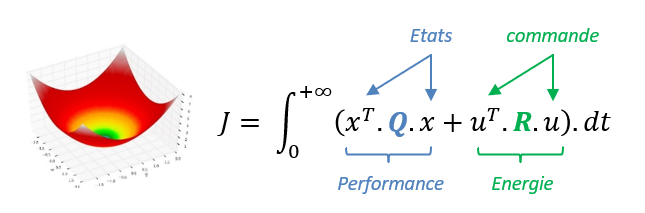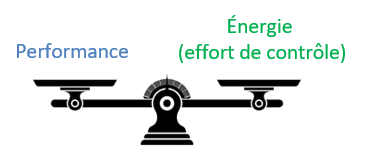

**Construisez les matrices Q et R avec la méthode de Brison ***(cours 08)*

*(**exemple** avec 4 états et 3 entrées)*

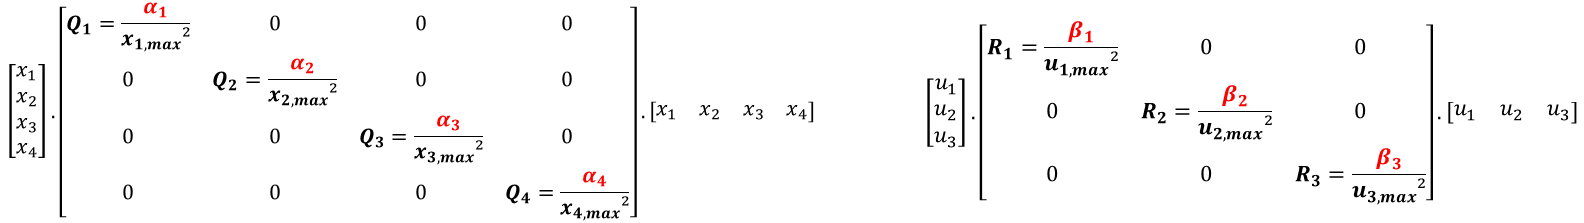

Les matrices Q et R sont les SEULS paramètres de réglage. Elles expriment un compromis entre performance et effort de commande.

***Rappel**** (cours 08)*

- $Q_i$  **↗** : on exige plus de performance sur $x_i$   → **pôles plus rapides **→ commande u plus sollicitée

- $R_i$  **↗** : on protège l'actionneur $u_i$   → **pôles plus lents **→ convergence plus douce, moins d’énergie dépensée

- C'est le ratio le ratio Q / R influence les gains LQR.

La normalisation de Brison équilibre les contraintes.

Les poids $\alpha_i$ et $\beta_i$ donnent ensuite des directions de design pour l'équilibre Q / R

### 5.1. Normalisation de Brison

Estimer les écarts maximaux attendus sur : 

- les états

- la commande virtuelle (plus facile à dimentionner, nous repasserons ensuite aux entrées moteurs avec : $R_{\textrm{mot}} =M^T \ldotp R_{\textrm{virt}} \ldotp M$)

**Attention, **les $x_{i,\max } \;/\;u_{i,\max }$ sont les ÉCARTS MAXIMAUX TOLÉRÉS pendant le transitoire.

=> Ce n'est PAS l'amplitude totale du déplacement.

=> Ce n'est PAS la limite physique du capteur ou de l'actionneur.

        **Proposition de dimensionnement cohérent avec la dynamique du système :**

-         x_max(position)  = v_ref  × τ_x/y/z

-         x_max(vitesse)   = v_ref             (directement le rate limiter)

-         x_max(angle)     = min( limite_linéarisation , v_ang_ref × τ_angle )

-         x_max(intégral)  = e_typique × τ_rejet

        où :

-         τ_x/y/z est la constante de temps VISÉE pour les suivis de consigne 

-         τ_angle est la constante de temps VISÉE pour l'équilibre de l'assiette / heading 

-         T_rejet est la constante de temps VISÉE pour le rejet de perturbation des états intégraux

        **P.S. **Nos matrice Q et R étant construite diagonale, on ne tiens pas compte des couplages dynamique. 

        => Cette approche est donc plus un ordre de grandeur qu'une science exacte (besoin d'itérer)        

        **Hiérarchie temporelle des boucles (séparation temporelle ×3 à ×5)**

-         T_angles     — Angles φ,θ,ψ  (équilibre de l'assiette/heading : le plus rapide)

-         T_pos_xy    — Position horizontale x,y   => ~ 3-5× plus lent que T_angles

-         T_pos_z      — Altitude z                         => ~ 2× plus lent que T_angles

-         T_rejet        — Intégrateurs (rejet vent)   => ~ 3-5× plus lent que T_pos_xy

% Constantes de temps visée :
% -------------------------------------------------
% T_angles    = ...
% T_pos_xy    = ...
% T_pos_z     = ...
% T_rejet     = ...

% Normalisation Brison : Positions
% -------------------------------------------------
% x_max       = ...
% y_max       = ...
% z_max       = ...
% psi_max     = ...

% Normalisation Brison : Vitesses 
% -------------------------------------------------
% dx_max      = ...
% dy_max      = ...
% dz_max      = ...
% dpsi_max    = ...

% Normalisation Brison : Angles & Vitesses angulaires
% -------------------------------------------------
% phi_max     = ...
% theta_max   = ...
dphi_max    = phi_max/T_angles;
dtheta_max  = theta_max/T_angles;

% Normalisation Brison : Intégrateurs
% -------------------------------------------------
% ei_max      = [... , ... , ... , ...];
xi_max      = ei_max(1) * T_rejet;
yi_max      = ei_max(2) * T_rejet;
zi_max      = ei_max(3) * T_rejet;
psii_max    = ei_max(4) * T_rejet;

% Normalisation Brison : Commande sur u_virt
% -------------------------------------------------
margin_u    = 0.8; % marge d'utilisation moteurs
% T_dispo_max = margin_u * ...
% Cphi_max    = margin_u * ...
% Cthe_max    = margin_u * ...
% Cpsi_max    = margin_u * ...
uv_max = [T_dispo_max ; Cphi_max ; Cthe_max ; Cpsi_max];

% Poids normalisés
% -------------------------------------------------
x2_norm = 1 ./ ([x_max ; dx_max ; y_max ; dy_max ; z_max ; dz_max ; ...
                 phi_max ; dphi_max ; theta_max ; dtheta_max ; psi_max ; dpsi_max ; ...
                 xi_max ; yi_max ; zi_max ; psii_max]) .^ 2;

uv2_norm = 1 ./ ([uv_max(1) ; uv_max(2) ; uv_max(3) ; uv_max(4)]) .^ 2;

% Matrice de Brison normalisée :
% -------------------------------------------------
Q_Brison      = diag(x2_norm);
R_Brison_virt = diag(uv2_norm);

______________________________________________________________________________________________

**Design 02  : placement LQR de Brison neutre (**$\alpha_i$** et **$\beta_i$** = 1)**

______________________________________________________________________________________________

Q_neutre = Q_Brison;
R_neutre = params.M' * (R_Brison_virt) * params.M; % adaptation à u_mot

% K_LQR_neutre  = ...
% sysBF_LQR_neutre = ...

______________________________________________________________________________________________

**Design 03  : placement LQR de Brison optimisé (**$\alpha_i$** et **$\beta_i$ $\not=$** 1)**

Les poids de $\alpha_i$ et $\beta_i$ devront rester dans un ratio [0.1 - 10].

Un ratio maximum de 100 est suffisant si la normalisation de Brison est bien faite.

______________________________________________________________________________________________

alpha_i = [ 1 ; 1 ; ...     % penalité sur x, dx
            1 ; 1 ; ...     % penalité sur y, dy
            1 ; 1 ; ...     % penalité sur z, dz
            1 ; 1 ; ...     % penalité sur phi, p
            1 ; 1 ; ...     % penalité sur theta, q
            1 ; 1 ; ...     % penalité sur psi, r
            1 ; ...         % penalité sur ∫x
            1 ; ...         % penalité sur ∫y
            1 ; ...         % penalité sur ∫z
            1];             % penalité sur ∫psi

beta_i = [1 ; 1 ; 1 ; 1];   % protection sur u_virt

Q_opti = alpha_i .* Q_Brison;
R_opti = params.M' * (beta_i .* R_Brison_virt) * params.M; % adaptation à u_mot 

% K_LQR_opti  = ...
% sysBF_LQR_opti = ...

______________________________________________________________________________________________

**Comparaison des placements de pôles des designs obtenus**

______________________________________________________________________________________________

figure; 
pzp = pzplot(sysBF_default , sysBF_LQR_neutre , sysBF_LQR_opti); grid on;

colors = {[0.5 0.5 0.5], 'b', [0 0.7 0]};
for i = 1:3
    pzp.Responses(i).MarkerSize = 10;
    pzp.Responses(i).LineWidth  = 2;
    pzp.Responses(i).Color      = colors{i};
end
legend('design 01', 'design 02', 'design 03');
table([ pole(sysBF_default) ; NaN ; NaN ; NaN ; NaN] ,  pole(sysBF_LQR_neutre) , pole(sysBF_LQR_opti) , ...
        'VariableNames', {'Default', 'LQR_neutre', 'LQR_opti'})

**______________________________________________________________________________________**

## **6. Simulations comparées et résultats**

**A ce stade nous avons construit :**

**design 01 **=> Simulink : `Simulink_drone_BF`

-         contrôle en position (échelon)

-         placement manuel ("optimisé" pour échelon ~ 20-30m)   

-        $\emptyset$ saturations actionneurs

-        $\emptyset$ perturbations

-        $\emptyset$ retour intégral

**design 02 **=> Simulink : `Simulink_drone_BF_final`

-         contrôle en vitesse (rampe venant du rate limiter)

-         placement LQR Brison par défault ($\alpha_i$ et $\beta_i$ = 1)

-        $√$ saturations actionneurs

-        $√$ perturbations

-        $√$ retour intégral

**design 03 **=> Simulink : `Simulink_drone_BF_final`

-         comme design 02

-         placement LQR Brison optimisé ($\alpha_i$ et $\beta_i$ $\not=$ 1)

**L'objectif de cette partie est double :** 

- Comparer les designs pour justifier de la qualité du design optimisé

- Concevoir un environnement de test pour itérer sur $\alpha_i$ et $\beta_i$ de trouver le meilleur réglage pour la course de la partie 03 (course)

### **6.1. Simulations**

Réalisez les simulations successives :

`sim01`` = sim('`Simulink_drone_BF`');`

**config : **`sysBO_default ; x_init ; K_default ; N_default`

sysBO = sysBO_default; 
init = x_init; 
K = K_default; 
N = N_default;

bool.Unreal_Engine = false;
sim01 = sim('Simulink_drone_BF');

`sim02`` = sim('`Simulink_drone_BF_final`');`

**config : **`sysBO_aug ; x_init_aug ; K_LQR_neutre ; Ki_LQR_neutre ; xi_init`

**P.S. **Besoin de décomposer K et Ki pour Simulink (cf. TD 03)

% sysBO = ...
% init = ...
% K = ...
% Ki = ...
xi_init = -pinv(Ki)*K*init(1:12); % init etat intégral

bool.Unreal_Engine = false;
sim02 = sim('Simulink_drone_BF_final');

`sim02`` = sim('`Simulink_drone_BF_final`');`

**config : **`sysBO_aug ; x_init_aug ; K_LQR_opti ; Ki_LQR_opti ; xi_init`

**P.S. **Besoin de décomposer K et Ki pour Simulink (cf. TD 03)

% sysBO = ...
% init = ...
% K = ...
% Ki = ...
xi_init = -pinv(Ki)*K*init(1:12); % init etat intégral

bool.Unreal_Engine = false;
sim03 = sim('Simulink_drone_BF_final');

### 6.2. Comparaison et résultats 

Adaptez les arguments de la fonction `animation_result_drone() `pour comparer :

- sim02 **vs** sim 01

- sim03 **vs** sim 02

Modifier votre fonction d'affichage (partie 01) pour comparer ces designs

% animation_result_drone(...
% animation_result_drone(...

**Fonction d'affichage (partie 01) adaptée pour comparaison :**

**______________________________________________________________________________________**

## 7. Sauvegarde des modèles, design et résultats

Sauvegardez ici votre design LQR optimisé pour le réutiliser dans la partie suivante :

**J'impose la structure suivante :**

`GRP``_XX (à remplacer)`

`.drone_name`

`.drone_params`

`.drone_model`

`.design_LQR`

GRP_00.drone_name     = 'DJI_Phamtom4';
GRP_00.drone_params   = params;
GRP_00.drone_model    = sysBO_aug;
GRP_00.design_LQR     = K_LQR_opti;

save ('Projet_drone_design_GRP_00' , 'GRP_00'); 

**______________________________________________________________________________________**

## 8. Annexes

**Fonction d'affichage des résultats d'une simulation en boucle fermée**

**Fonction d'augmentation d'état intégral**

function [A_aug , B_aug , C_aug , D_aug] = augment_retour_int (A, B, C, D, Cs)

[n, m] = size(B);
p      = size(Cs, 1);

% --- Construction du système augmenté ---
A_aug = [A   , zeros(n, p) ; ...
         -Cs , zeros(p, p)];

B_aug = [B          ; ...
         zeros(p,m)];

C_aug = [C, zeros(n, p)];

D_aug = D;

end